clc
clear all
close all
pause('off')

## Inverted Pendulum Mini Project

We know that the Inverted Pendulum on a moving cart has Non-linear system of equations, with 2DOF (x and $\theta$), which result four coupled ODE

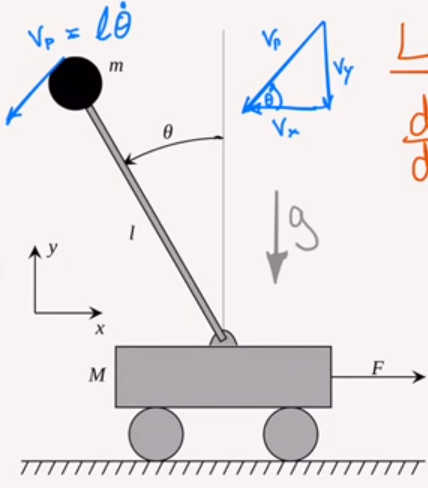         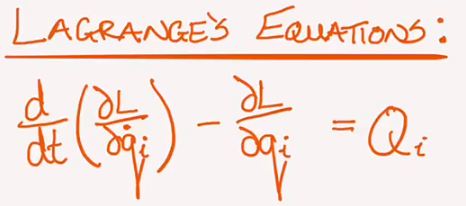

Using the Lagrange's equation above:

L = Kinetic Energy(T) - Potential Energy(V)

where, V = m.g.l.cos($\theta$) 

T = $\frac{1}{2}\ldotp M\ldotp {\dot{x} }^2 +\frac{1}{2}\ldotp M\ldotp {\left(V_P \right)}^2 \;$ = $\frac{1}{2}\ldotp M\ldotp {\dot{x} }^2 +\frac{1}{2}\ldotp M\ldotp \left({\left(V_x \right)}^2 +{\left(V_y \right)}^2 \right)$  $\Longrightarrow$  = $\frac{1}{2}\ldotp M\ldotp {\dot{x} }^2 +\frac{1}{2}\ldotp m\ldotp {\left(\left(\dot{x} \right)-l\ldotp \theta^˙ \ldotp \mathrm{cos}\left(\theta^˙ \right)\right)}^2 +\frac{1}{2}\ldotp m\ldotp {\left(-l\ldotp \theta^˙ \ldotp \mathrm{sin}\left(\theta^˙ \right)\right)}^2$

Therefore, L = -m$\dot{x}$.l.$\theta^˙ \ldotp$cos($\theta$) + $\frac{1}{2}\ldotp \left(M+m\right)\ldotp {\dot{x} }^2$ -m$\ldotp g$.l$\ldotp$cos($\theta$) + $\frac{1}{2}\ldotp \left(m\right)\ldotp l^2 \ldotp {\theta^˙ }^2$

Substituting Value of L into the Lagrange's equation -

For $q_1$** = x** :            

For $q_2$** = **$\theta$ :          

Our states are: $x=\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
\theta \\
\theta^˙ 
\end{array}\right\rbrack$

We can linearize the Non-linearized system around certain fixed points, where:

x = free

$\dot{x}$ = 0;

$\theta$ = 0 (Pendulum up), $\pi$ (Pendulum down)

$\theta^˙$ = 0;

$\dot{x} =\mathrm{Ax}+\mathrm{Bu}$, 


$$y=\mathrm{Cx}$$


# Defining Parameters

m = 1;              % Mass of the pendulum in kg
M = 5;              % Mass of the cart in kg
L = 2;              % Length of pendulum center of mass in m
g = -10;            % Acceleration due to gravity down in m/s^2
d = 1;              % damping Ratio, 1 is critically damped

s = 1;              % Pendulum is up and vertical at s = 1

# Linearization of the Non-Linear equations

% Linearized A and B matrix about the above fixed values using Jacobian

A = [0              1                   0              0;...
     0           -d/M              -m*g/M              0;...
     0              0                   0              1;...
     0      -s*d/(M*L)     -s*(m+M)*g/(M*L)            0];

B = [0; 1/M; 0; s*1/(M*L)];

fprintf(' Matrix A for the State Space Model is: ');

 Matrix A for the State Space Model is: 

disp(A);

         0    1.0000         0         0
         0   -0.2000    2.0000         0
         0         0         0    1.0000
         0   -0.1000    6.0000         0




fprintf(' Matrix B for the State Space Model is: ');

 Matrix B for the State Space Model is: 

disp(B);

         0
    0.2000
         0
    0.1000




fprintf(' Eigen Values of the State Space Model is: ');

 Eigen Values of the State Space Model is: 


disp(eig(A));

         0
   -2.4674
   -0.1665
    2.4339




% One of the eigen value is +ve, therefore currently our system is
% unstable!, which for us right now stability exists when the pendulum is
% upright


# Controllability

If the rank of the controllability matrix is equal to the maximum possible rank, then the system is **controllable**.

In our Case, N = 4, and thus K martrix is full rank iff rank(K) = 4

K_Controllability = ctrb(A,B);
Rank_K_Controllability = rank(K_Controllability);

disp(' The rank of the controllability matrix is: ');

 The rank of the controllability matrix is: 


disp(rank(ctrb(A,B)));  % is it controllable

     4




if Rank_K_Controllability == 4
    disp(' Thus, the LTI system is completely controllable ');
end

 Thus, the LTI system is completely controllable 


# Full-State Feedback Controller

## Pole Placement Method

The control law is u = -Kx

which makes our A_closed = (A -B.K)

K is the Proportional gain which is found by placing our poles at specific locations that we want !! and thus we can verify by checking eig(A_closed) to see if the eigen values of A_closed are the same as the places we wanted the poles to be 

#### **Trial 1**

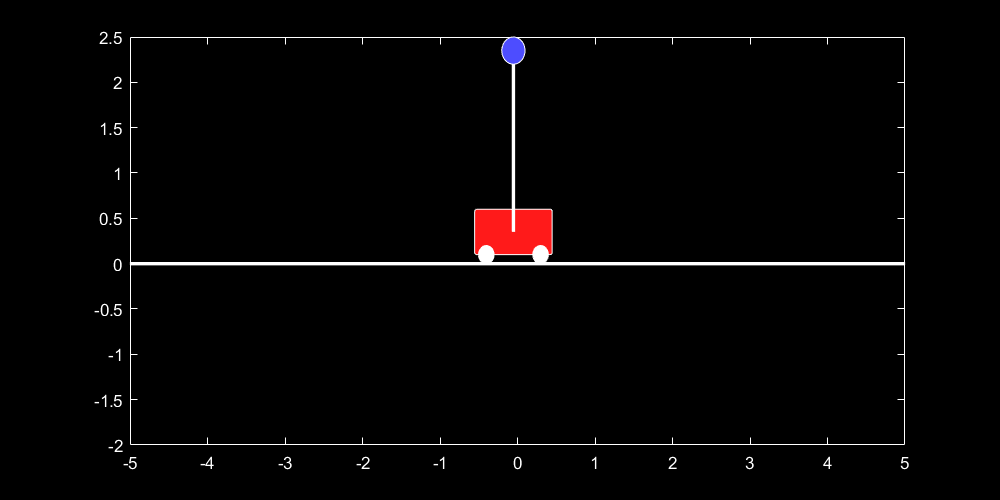

P1 = [-0.3; -0.4; -0.5; -0.6]; % desired CL pole locations
K1 = place(A, B, P1); % proportional gains
A_closed1 = A - B*K1; % equivalent open-loop A for the closed-loop system

% Simulating
% Cartpend gives me State Space equations that are found using lagrange
% equations

% One of the inputs of cartpend is the Force u, where for our closed loop control law u = -Kx
% Here for cartpend we have denoted x(states) as y, 
% and we are writing u = -K(x- Reference Value)
% Reference value is set to initial condition because we want the inverted
% pendulum cart to reach those states eventualtually than damping to 0

% So technically my reference value here is x = 1, xdot = 0, theta = pi and
% thetadot = o, so i want the cart to end at these reference values
tspan = 0:.001:30;
if(s==-1)
    y0 = [0; 0; 0; 0];
    [t,y] = ode45(@(t,y)cartpend(y,m,M,L,g,d,-K1*(y-[4; 0; 0; 0])),tspan,y0);
elseif(s==1)
    y0 = [-3; 0; pi+.1; 0];
    [t,y] = ode45(@(t,y)cartpend(y,m,M,L,g,d,-K1*(y-[0; 0; pi; 0])),tspan,y0);
else 
end




myVideo = VideoWriter('PolePlace_Trial1'); % open video file
myVideo.FrameRate = 35;  
open(myVideo)

for k=1:100:length(t)
    drawcartpend_bw(y(k,:),m,M,L);
    pause(0.01)  % Pause and grab frame
    frame = getframe(gcf); % get frame
    writeVideo(myVideo, frame);
end

close(myVideo);

**Trial 2**

We want the inverted pendulum to be stabilized faster and not move off screen, thus to get a faster response we move the poles farther to the left

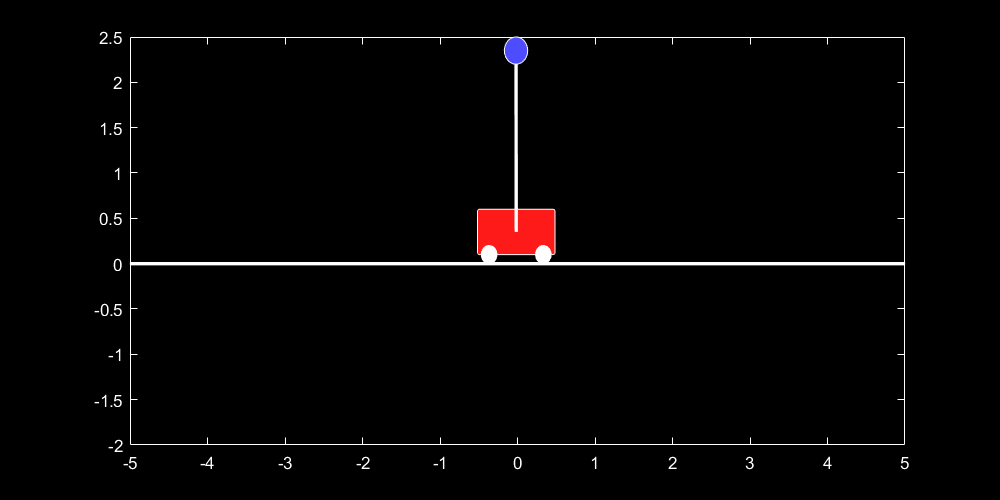

P2 = [-1; -1.1; -1.2; -1.3]; % desired CL pole locations
K2 = place(A, B, P2); % proportional gains
A_closed2 = A - B*K2; % equivalent open-loop A for the closed-loop system

% Simulating
% Cartpend gives me State Space equations that are found using lagrange
% equations

% One of the inputs of cartpend is the Force u, where for our closed loop control law u = -Kx
% Here for cartpend we have denoted x(states) as y, 
% and we are writing u = -K(x- Reference Value)
% Reference value is set to initial condition because we want the inverted
% pendulum cart to reach those states eventualtually than damping to 0

% So technically my reference value here is x = 1, xdot = 0, theta = pi and
% thetadot = o, so i want the cart to end at these reference values 
tspan = 0:.001:10;
if(s==-1)
    y0 = [0; 0; 0; 0];
    [t,y] = ode45(@(t,y)cartpend(y,m,M,L,g,d,-K2*(y-[4; 0; 0; 0])),tspan,y0);
elseif(s==1)
    y0 = [-3; 0; pi+.1; 0];
    [t,y] = ode45(@(t,y)cartpend(y,m,M,L,g,d,-K2*(y-[0; 0; pi; 0])),tspan,y0);
else 
end

myVideo = VideoWriter('PolePlace_Trial2'); % open video file
myVideo.FrameRate = 35;  
open(myVideo)

for k=1:100:length(t)
    drawcartpend_bw(y(k,:),m,M,L);
    pause(0.01)  % Pause and grab frame
    frame = getframe(gcf); % get frame
    writeVideo(myVideo, frame);
end

close(myVideo);

**Trial 3**

Let's try and be more aggressive and move poles even farther left

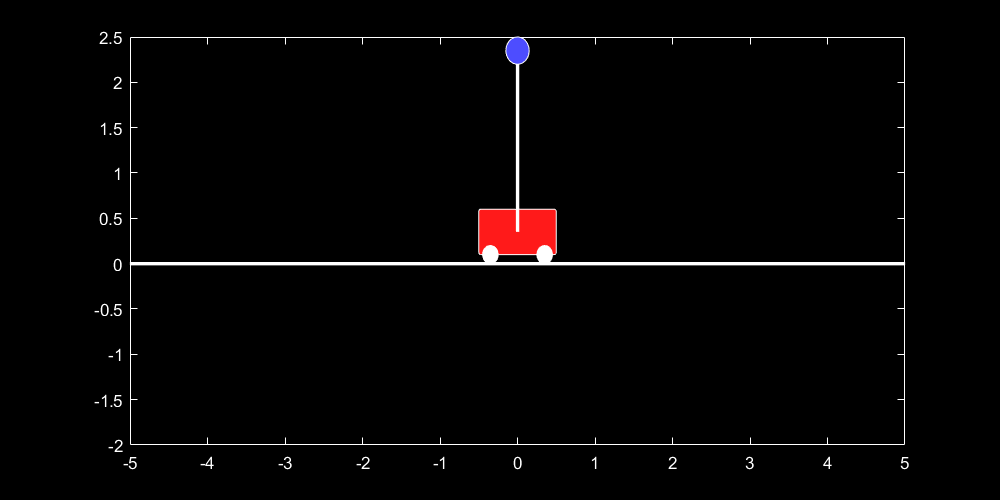

P3 = [-2; -2.1; -2.2; -2.3]; % desired CL pole locations
K3 = place(A, B, P3); % proportional gains
A_closed3 = A - B*K3; % equivalent open-loop A for the closed-loop system

% Simulating
% Cartpend gives me State Space equations that are found using lagrange
% equations

% One of the inputs of cartpend is the Force u, where for our closed loop control law u = -Kx
% Here for cartpend we have denoted x(states) as y, 
% and we are writing u = -K(x- Reference Value)
% Reference value is set to initial condition because we want the inverted
% pendulum cart to reach those states eventualtually than damping to 0

% So technically my reference value here is x = 1, xdot = 0, theta = pi and
% thetadot = o, so i want the cart to end at these reference values 
tspan = 0:.001:10;
if(s==-1)
    y0 = [0; 0; 0; 0];
    [t,y] = ode45(@(t,y)cartpend(y,m,M,L,g,d,-K3*(y-[4; 0; 0; 0])),tspan,y0);
elseif(s==1)
    y0 = [-3; 0; pi+.1; 0];
    [t,y] = ode45(@(t,y)cartpend(y,m,M,L,g,d,-K3*(y-[0; 0; pi; 0])),tspan,y0);
else 
end

myVideo = VideoWriter('PolePlace_Trial3'); % open video file
myVideo.FrameRate = 35;  
open(myVideo)

for k=1:100:length(t)
    drawcartpend_bw(y(k,:),m,M,L);
    pause(0.01)  % Pause and grab frame
    frame = getframe(gcf); % get frame
    writeVideo(myVideo, frame);
end

close(myVideo);

# LQR(Linear-Quadratic Regulator) Design

Output Vector = C * State Vector + D * Input Vector

The LQR function requires a state weighing matrix **Q** and an actuator weighing matrix **R**.

State weighing matrix **Q**:

In order to design the State weighing matrix Q, we will use the "output weighing"

**Note**: Varying the weighting matrices **Q** and **R** allows us to trade off the "size" of the state response with the size of the control effort. For example,

If $\left|Q\right|$ <<$\left|R\right|$, then cost function will minimize the amount of control effort needed (i.e. gains will be small).

If $\left|Q\right|$ >>$\left|R\right|$, then cost function will minimize the state response without regard to amount of control effort needed (i.e. gains will be large).

**Note**: Q is technically going to be a diagonal matrix, with each diagonal element corresponding to a specific state, so for example we want state element 1 to have the least error then we can make the diagonal element from the Q  matrix corresponding to state element 1 larger than others to do so.

R is similar to Q but acts on the input vector.

% Q (State wighing matrix) is:
Q = diag([10 1 10 100]);

% R (Input weighing matrix) is:
R = .1; % We just have one input of the force u, I am trying to make R less expensive because I dont care about the expenses of my motor, as If I have all the capital to spend on the best motor producing required force possible

% Our control law is still u = -K*x
K_lqr = lqr(A,B,Q,R); % where K is my state feedback gain matrix

disp(' Poles placed by LQR controller: ');

 Poles placed by LQR controller: 


disp(eig(A-B*K_lqr));

  -4.5074 + 0.0000i
  -0.8687 + 0.8732i
  -0.8687 - 0.8732i
  -1.4624 + 0.0000i



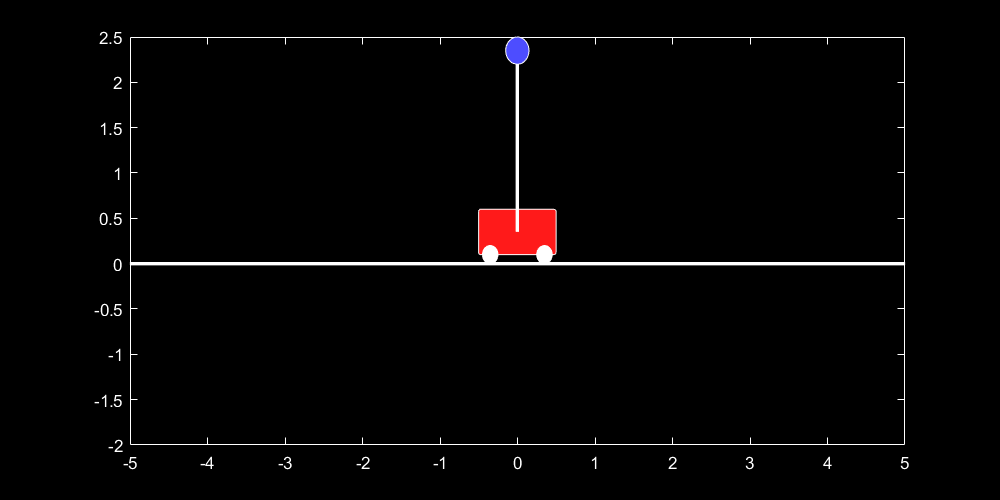


tspan = 0:.001:10;
if(s==-1)
    y0 = [0; 0; 0; 0];
    [t,y] = ode45(@(t,y)cartpend(y,m,M,L,g,d,-K_lqr*(y-[4; 0; 0; 0])),tspan,y0);
elseif(s==1)
    y0 = [-3; 0; pi+.1; 0];
    [t,y] = ode45(@(t,y)cartpend(y,m,M,L,g,d,-K_lqr*(y-[0; 0; pi; 0])),tspan,y0);
else
    
end

myVideo = VideoWriter('LQR_Trial'); % open video file
myVideo.FrameRate = 35;  
open(myVideo)

for k=1:100:length(t)
    drawcartpend_bw(y(k,:),m,M,L);
    pause(0.01)  % Pause and grab frame
    frame = getframe(gcf); % get frame
    writeVideo(myVideo, frame);
end

close(myVideo);

# Observability

The** reason** we need to check for observability is because just like controller design problem we check for controllability, we need to check if the observability matrix is full rank such that we can arbitarily place poles of an observer we design.

If the rank of the observability matrix is equal to the maximum possible rank, then the system is **observable**.

**For example**: If we have aobservability matrix O, that has a rank N, where N is the number of columns of A matrix of size NxN, and matrix O is defined as $O=\left\lbrack C^{\prime } ,{A^{\prime } C}^{\prime } ,{A^{\prime } }^2 C^{\prime } ,{A^{\prime } }^3 C^{\prime } ,\ldotp \ldotp \ldotp \ldotp {A^{\prime } }^{N-1} C^{\prime } \right\rbrack$

In our Case, N = 4, and thus O martrix is full rank iff rank(O) = 4

**Note**: We also need to check which components of the Output Matrix feeding into the observable system after being multiplied by Matrix C have an impact on the observatibility of the system.

**Conclusion**: Since none of the subsets or combination of subsets of the outputs result in full rank observable matrix therefore there is no subset which is able to result in a fully observable system.

C1 = [1 0 0 0]; % Assuming that we are just measuring the cart's position x 

O_Observability_x = obsv(A,C1); % Observability matrix with no outputs zero'd
Rank_O_Observability_x = rank(O_Observability_x);

disp(' The rank of the observability matrix is: ');

 The rank of the observability matrix is: 


disp(Rank_O_Observability_x);

     4



if Rank_O_Observability_x == 4
    disp(' Thus, the LTI system is completely observable ');
end

 Thus, the LTI system is completely observable 



% So we conclude that if we just calculate/measure position of cart then
% the system is completely observable 


% Let's see if other measurements are observable or not 

C2 = [0 0 1 0]; % Assuming that we are just measuring the pendulum's angle theta 

O_Observability_theta = obsv(A,C2); % Observability matrix with no outputs zero'd
Rank_O_Observability_theta = rank(O_Observability_theta);

disp(' The rank of the observability matrix is: ');

 The rank of the observability matrix is: 


disp(Rank_O_Observability_theta);

     3



if Rank_O_Observability_theta == 4
    disp(' Thus, the LTI system is completely observable ');
else 
    disp(' the LTI system is not completely observable ');
end

 the LTI system is not completely observable 



% So we conclude that if we just calculate/measure theta then
% the system is not completely observable 
% Note: that is also the case for other measurements xdot, thetadot, if you
% check their ranks respectively


% Let's also check which measurement is best for observability if we omit x

C_omitX_measurexdot = [1 0 0];
A_omitX_measurexdot = A(2:end, 2:end);
B_omitX_measurexdot = B(2:end);

O_Observability_omitX_measurexdot = obsv(A_omitX_measurexdot,C_omitX_measurexdot); 
Rank_O_Observability_omitX_measurexdot = rank(O_Observability_omitX_measurexdot);

% Since it is full rank now if the rank is 3 because we have omitted one of
% the states
disp(' The rank of the observability matrix is: ');

 The rank of the observability matrix is: 


disp(Rank_O_Observability_omitX_measurexdot);

     3



if Rank_O_Observability_omitX_measurexdot == 3
    disp(' Thus, the LTI system is completely observable ');
else 
    disp(' the LTI system is not completely observable ');
end

 Thus, the LTI system is completely observable 



C_omitX_measuretheta = [0 1 0];
A_omitX_measuretheta = A(2:end, 2:end);

O_Observability_omitX_measuretheta = obsv(A_omitX_measuretheta,C_omitX_measuretheta); 
Rank_O_Observability_omitX_measuretheta = rank(O_Observability_omitX_measuretheta);

disp(' The rank of the observability matrix is: ');

 The rank of the observability matrix is: 


disp(Rank_O_Observability_omitX_measuretheta);

     3



if Rank_O_Observability_omitX_measuretheta == 3
    disp(' Thus, the LTI system is completely observable ');
else 
    disp(' the LTI system is not completely observable ');
end

 Thus, the LTI system is completely observable 



C_omitX_measurethetadot = [0 0 1];
A_omitX_measurethetadot = A(2:end, 2:end);

O_Observability_omitX_measurethetadot = obsv(A_omitX_measurethetadot,C_omitX_measurethetadot); 
Rank_O_Observability_omitX_measurethetadot = rank(O_Observability_omitX_measurethetadot);

disp(' The rank of the observability matrix is: ');

 The rank of the observability matrix is: 


disp(Rank_O_Observability_omitX_measurethetadot);

     3



if Rank_O_Observability_omitX_measurethetadot == 3
    disp(' Thus, the LTI system is completely observable ');
else 
    disp(' the LTI system is not completely observable ');
end

 Thus, the LTI system is completely observable 



% So we conclude that the system is completely observable at measurement of any state
% if we ommit x


## Observability Gramian

So far we just checked whether or not the system is observable but now Observability gramian gives us the indication of a metric of which one has a better observability

Note: Bigger the determinant of the gramian, bigger the noise to disturbance ratio we can pull out, bigger the volume of observibility elipsoid !!

Thus we need bigger determinant possible which is better !

% Now lets the check the Observability gramian

% Note: you will notice that if you calculate the gramian determinant at
% s=1 (Pendulum is upright), you will get an error because the system is
% unstable !! We can calculate gramian when the system is stable so we set
% s = -1 ! 

s_stable = -1;
A_checkgramian = [0              1                   0                            0;...
                  0           -d/M              -m*g/M                            0;...
                  0              0                   0                            1;...
                  0      -s_stable*d/(M*L)     -s_stable*(m+M)*g/(M*L)            0];

B_checkgramian = [0; 1/M; 0; s_stable*1/(M*L)];

A_checkgramian = A_checkgramian(2:end, 2:end);
B_checkgramian = B_checkgramian(2:end);

D_omitX_measurexdot = zeros(size(C_omitX_measurexdot,1),size(B_checkgramian,2));
sys_omitX_measurexdot = ss(A_checkgramian,B_checkgramian,C_omitX_measurexdot,D_omitX_measurexdot);
disp(' Determinant of gramian if we just measure xdot ');

 Determinant of gramian if we just measure xdot 


disp(det(gram(sys_omitX_measurexdot,'o')));

   50.0000




D_omitX_measuretheta = zeros(size(C_omitX_measuretheta,1),size(B_checkgramian,2));
sys_omitX_measuretheta = ss(A_checkgramian,B_checkgramian,C_omitX_measuretheta,D_omitX_measuretheta);
disp(' Determinant of gramian if we just measure theta ');

 Determinant of gramian if we just measure theta 


disp(det(gram(sys_omitX_measuretheta,'o')));

    0.0313




D_omitX_measurethetadot = zeros(size(C_omitX_measurethetadot,1),size(B_checkgramian,2));
sys_omitX_measurethetadot = ss(A_checkgramian,B_checkgramian,C_omitX_measurethetadot,D_omitX_measurethetadot);
disp(' Determinant of gramian if we just measure theta dot ');

 Determinant of gramian if we just measure theta dot 


disp(det(gram(sys_omitX_measurethetadot,'o')));

    0.0313




% So we conclude that we have larger volume of observability elipsoid if we
% only measure xdot, so we know that its easier for us to observe the
% system if we just measure xdot

# Reason for Full-State Estimation

So far we were using controllability ctrb(A,B), where we answer the question if we can **control** the system with the available number of states (Not always all the possible states),  most of the time we do not need all the possible states of the systems for controlling the system, that is what is happening so far where **For example**, we have n states, and q inputs, and y = C.x, here we most probably y belong some p states < n possible states, that is we might just be using p states to attain full controllability of the systems

Now, we are going to look at observability obs(A,C), where we answer the question if we can **estimate **all states x from a time series of my measurement y(t).

The **reason** is simple that if we can estimate full-states of the system, then it is much easier to know an optimal full state controller that works really well.

# Kalman Filter

**Kalman Filter** is an optimal linear state Estimator. This dynamic observer is the optimal solution to the Linear Quadratic Gaussian (LQG) problem of estimating the instantaneous states of a dynamic system when the process noise and measurement noise are white and Gaussian. 

Kalman Filter estimates all of the states of the system, it measures u and y & has a model of A, B and C !!!

The **luenberger observer** that I have practiced before in my AUV project is same as Kalman Filter and is sometimes considered as a sub-optimal Kalman Filter. 

So Kalman Filter has the same structure as the Luenberger Observer but with "optimally" chosen observer gains.


$$\dot{x} =\mathrm{Ax}+\mathrm{Bu}+w_d$$



$$y=\mathrm{Cx}+w_n$$


Where: $w_d$ is Gaussian (Disturbance), $V_d$ is Variance (Disturbance) and $w_n$ is Gaussian (noise), $V_n$ is Variance (Noise)

**But Note**: If the Kalman filter has really bad Sensor Noise ($w_n$), then it cant trust y very much and thus have to rely on its model (A and B) more, but if it has really big disturbances ($w_d$) then it should trust is measurements (y) more.

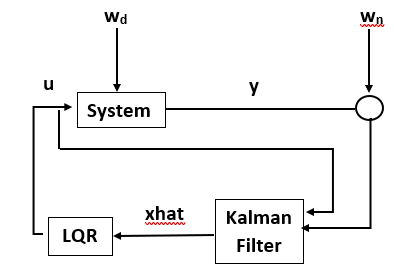

**Note**: The Augmented state-space system:

$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\widehat{x} } 
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{cc}
A & -\mathrm{BG}\\
\mathrm{KC} & \left(A-\mathrm{KC}-\mathrm{BG}\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
F & 0\\
0 & K
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w_d \\
w_n 
\end{array}\right\rbrack$

can also be written as $\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\widehat{x} } 
\end{array}\right\rbrack$ = $\overline{A}$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$ + $\bar{B} u$

$\left\lbrack \begin{array}{c}
y\\
\hat{y} 
\end{array}\right\rbrack \;$ =  $\left\lbrack \begin{array}{cc}
C & -\mathrm{DG}\\
0 & C-\mathrm{DG}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w_d \\
w_n 
\end{array}\right\rbrack$

can also be written as $\left\lbrack \begin{array}{c}
y\\
\hat{y} 
\end{array}\right\rbrack$ = $\bar{C}$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$ + $\bar{D} u$

Here $\hat{x}$ and $\hat{y}$ are the dynamic estimator x and y's, such that the state estimation error dynamics is e = x - $\hat{x}$

also, K is the Kalman filter gain, 

$V_d$ = $\left\lbrack \begin{array}{cccc}
\ldotp 1 & 0 & 0 & 0\\
0 & \ldotp 1 & 0 & 0\\
0 & 0 & \ldotp 1 & 0\\
0 & 0 & 0 & \ldotp 1
\end{array}\right\rbrack$

$V_n$ = 1

Here for Kalman FIlter, similar to our weighing matrixes Q and R in the LQR controller; for our LQE (Kalman Filter) we have Vd and Vn, so if we have our Disturbance noise/ Model uncertainty is high then we make $V_d$ larger. if we have sensor noise larger then we make $V_n$ larger

So we will have 

$\dot{x} =\mathrm{Ax}+\mathrm{Bu}+\;$$V_d$.d + 0.n

$y=\mathrm{Cx}+D\ldotp u+0\ldotp d+\;$$V_n$.n  ; D is primarily just 0 in our case 

D in the augmented case (lumped up together) above = $\left\lbrack \begin{array}{ccc}
0 & 0 & V_n 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
u\\
d\\
n
\end{array}\right\rbrack$

% Trying to simulate for pendulum down
s_estimation = -1;

A_estimation = [0              1                   0              0;...
     0           -d/M              -m*g/M              0;...
     0              0                   0              1;...
     0      -s_estimation*d/(M*L)     -s_estimation*(m+M)*g/(M*L)            0];

B_estimation = [0; 1/M; 0; s_estimation*1/(M*L)];



%  Augmented system with disturbances and noise
Vd = .1*eye(4);         % disturbance covariance
Vn = 1;                 % noise covariance

% augment inputs to include disturbance and noise
BF = [B_estimation Vd 0*B_estimation];  % Takes an input u, d and n

% Note: This is big augmented state space system, which gives you the
% estimated state x
% build big state space system that takes in disturbances, inputs and noise... with single output
sysC = ss(A_estimation,BF,C1,[0 0 0 0 0 Vn]); 


% Note: this is the Full state System, which gives you true full-state (all
% 4 states)
% system with full state output, disturbance, no noise
sysFullOutput = ss(A_estimation, BF, eye(4), zeros(4,size(BF,2)));  % eye(4) because I want to measure all 4 states 

%  Build Kalman filter
% [Kf,P,E] = lqe(A,Vd,C1,Vd,Vn);  % design Kalman filter

% alternatively, possible to design using "LQR" code
Kf = (lqr(A_estimation',C1',Vd,Vn))'; % Where we try to trick the lqr controller that we are giving in A and B (A' and C'), and our weight matrixes Q and R (Vd and Vn)

% Kalman filter estimator
% Here we define a state space system for just Kalman Filter which takes in u and y (which is B anf Kf in our case), then
% we have C as eye(4) because we want to estimate all 4 states and then our
% D is just 0
sysKF = ss(A_estimation-Kf*C1,[B_estimation Kf],eye(4),0*[B_estimation Kf]); 

dt = .01;
t = dt:dt:50;

uDIST = randn(4,size(t,2));         %disturbance
uNOISE = randn(size(t));            %noise
u = 0*t;                            % we start off with 0 input 
u(100:120) = 100;                   % impulse, then at some time forward input force
u(1500:1520) = -100;                % impulse, followed by backward input force

uAUG = [u; Vd*Vd*uDIST; uNOISE];

% Full state measurement with noise
[y,t] = lsim(sysC,uAUG,t);


% True Full state without noise
[xtrue,t] = lsim(sysFullOutput,uAUG,t);


% Simulating Kalman Filter estimate
[x,t] = lsim(sysKF,[u; y'],t);

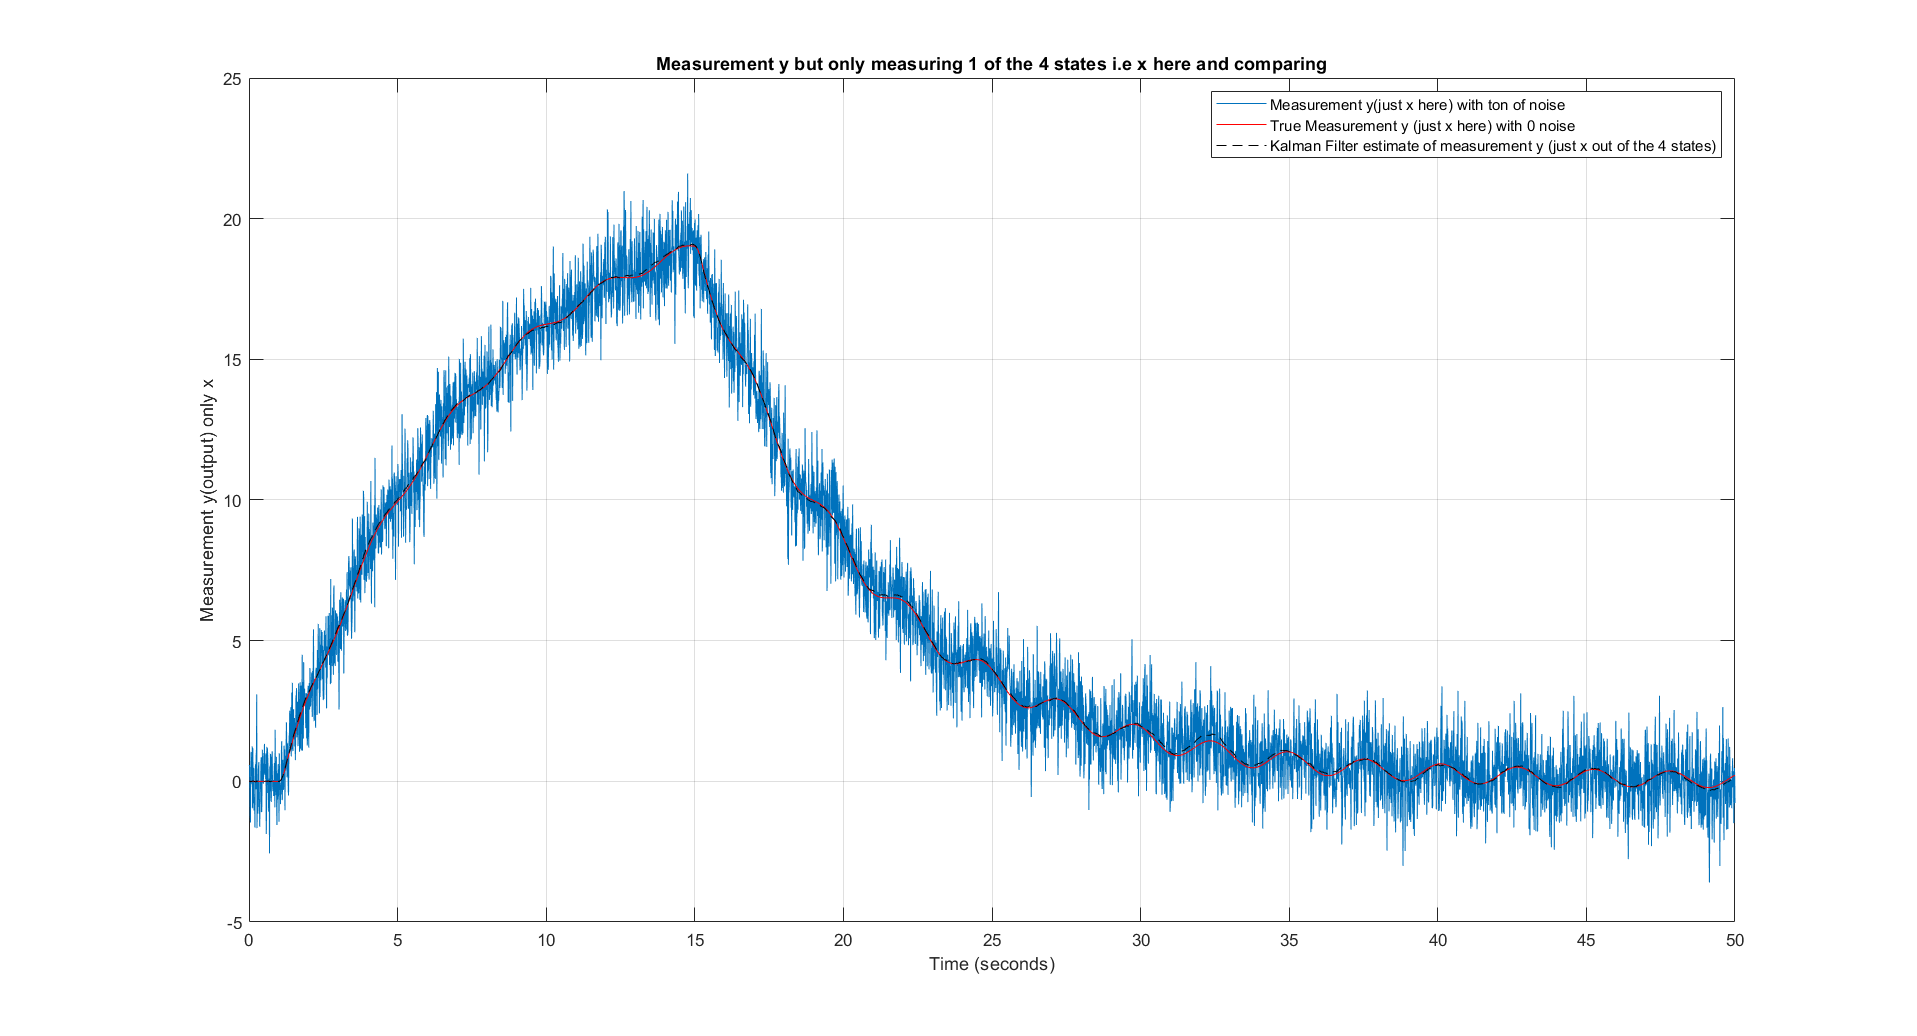


% Plots 

figure
plot(t,y)
hold on
grid on
plot(t,xtrue(:,1),'r'); % No noise so we just want to know what the underlying full state is
plot(t,x(:,1),'k--'); % Kalman filter estimate of state x
hold off 
legend('Measurement y(just x here) with ton of noise', 'True Measurement y (just x here) with 0 noise', 'Kalman Filter estimate of measurement y (just x out of the 4 states) ');
xlabel('Time (seconds)');
ylabel('Measurement y(output) only x');
title('Measurement y but only measuring 1 of the 4 states i.e x here and comparing');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

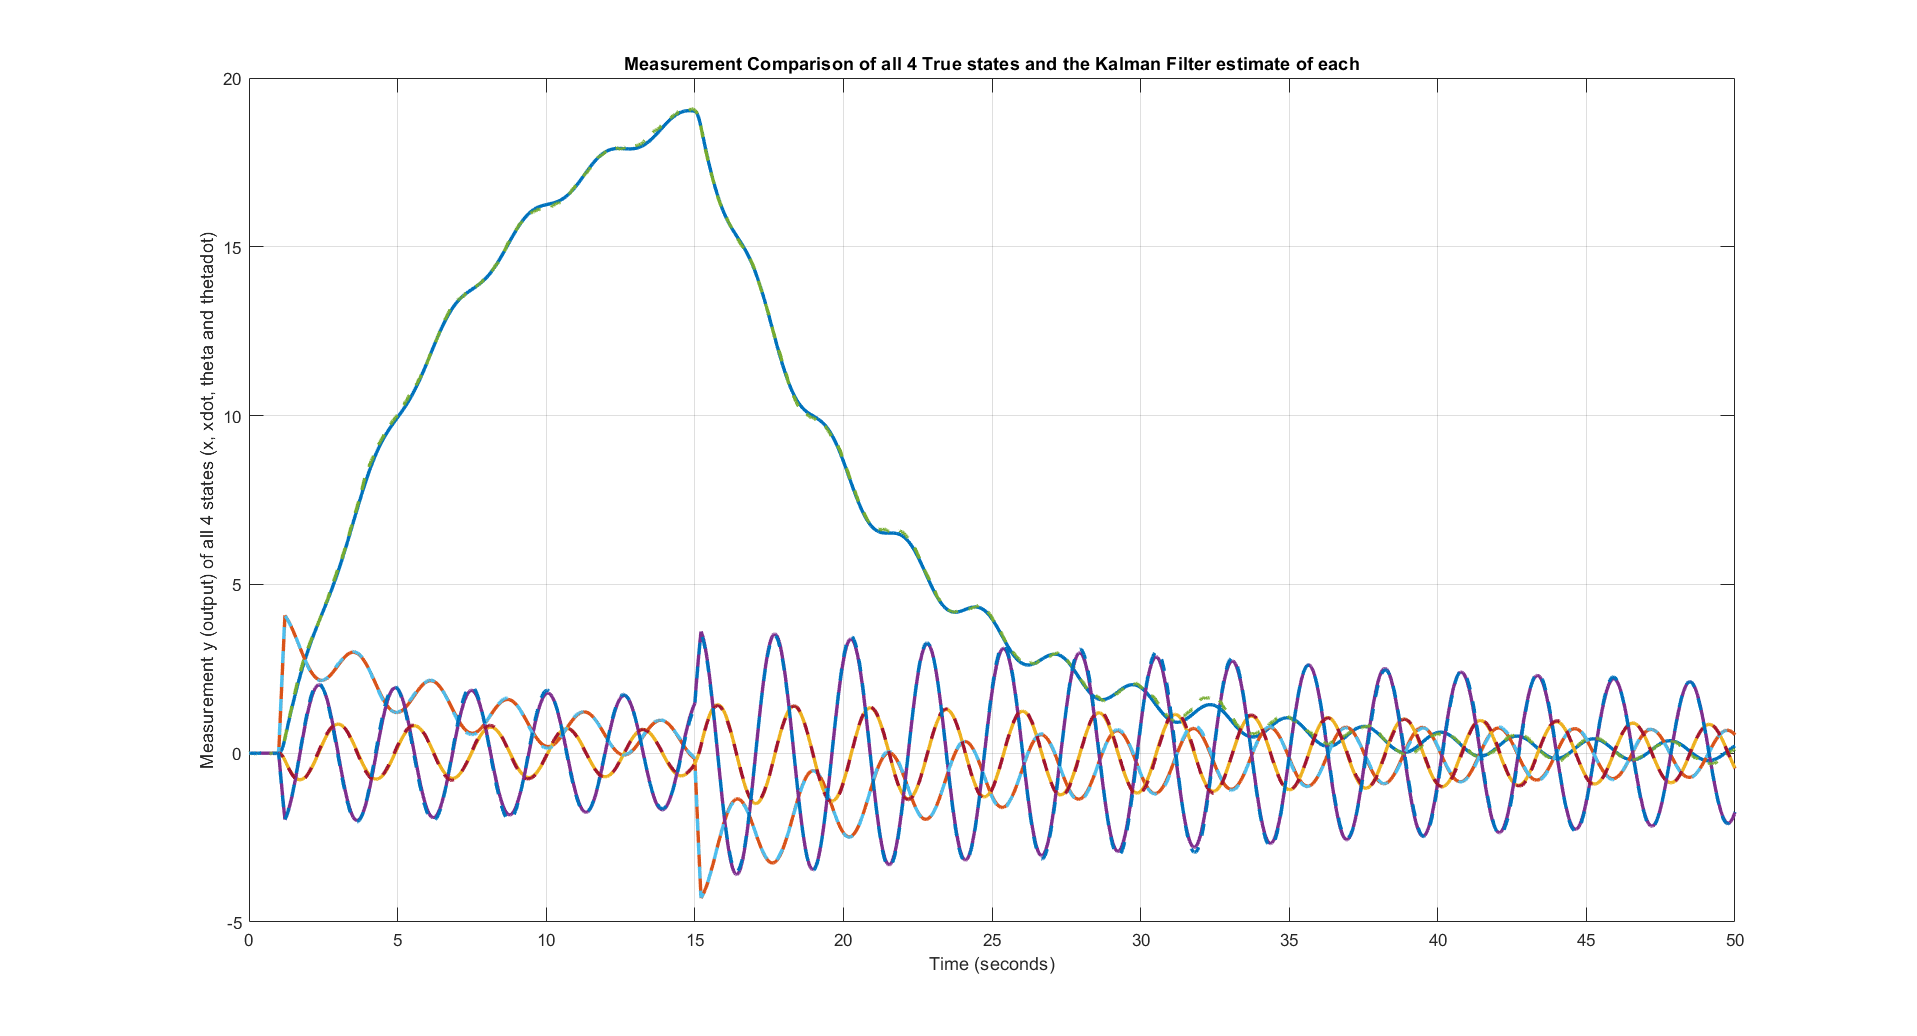



% Lets plot the Kalman Filter estimate and Trus Full state for all the 4
% states now
figure
plot(t, xtrue,'-', t, x,'--','LineWidth',2);
grid on 
xlabel('Time (seconds)');
ylabel('Measurement y (output) of all 4 states (x, xdot, theta and thetadot)');
title('Measurement Comparison of all 4 True states and the Kalman Filter estimate of each');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

# Linear Quadratic Gaussian Controller


$$\varepsilon =x-\hat{x}$$


LQR -> $A-B\ldotp K_r$

Kalman Filter (L.Q.E) -> $A-K_f \ldotp C$

So in the setup below my estimator $\varepsilon$ dynamics are stabilized by the Kalman Filter and the full state dynamics are stabilized by the LQR controller

$\left\lbrack \begin{array}{c}
\dot{x} \\
\varepsilon^˙ 
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{cc}
A-B\ldotp K_r  & B\ldotp K_r \\
0 & A-K_f \ldotp C
\end{array}\right\rbrack$.$\left\lbrack \begin{array}{c}
x\\
\varepsilon 
\end{array}\right\rbrack$ + $\left\lbrack \begin{array}{cc}
I & 0\\
I & -K_f 
\end{array}\right\rbrack$.$\left\lbrack \begin{array}{c}
\omega_d \\
\omega_n 
\end{array}\right\rbrack$

% In the Simulink Model Attached to source

